clear; close all; clc

imageDir = fullfile("data")

imageDir = "data"

imds = imageDatastore(imageDir)

imds =   ImageDatastore のプロパティ:

                       Files: {
                              '/Users/labd/MATLAB/projects/itigo/data/Copy_2_of_itigo15.jpg';
                              '/Users/labd/MATLAB/projects/itigo/data/Copy_2_of_itigo16 (1).jpeg';
                              '/Users/labd/MATLAB/projects/itigo/data/Copy_2_of_itigo17 (1).jpeg'
                               ... and 30 more
                              }
                     Folders: {
                              '/Users/labd/MATLAB/projects/itigo/data'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


labelDir = fullfile("labeldata")

labelDir = "labeldata"

classNames = ["itigo","nouen"];

labelIDs = [1 2];

pxds = pixelLabelDatastore(labelDir,classNames,labelIDs)

pxds =   PixelLabelDatastore のプロパティ:

                       Files: {33×1 cell}
                  ClassNames: {2×1 cell}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage
    AlternateFileSystemRoots: {}


trainingData = pixelLabelImageDatastore(imds,pxds)

trainingData =   pixelLabelImageDatastore のプロパティ:

                  Images: {33×1 cell}
          PixelLabelData: {33×1 cell}
              ClassNames: {2×1 cell}
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: []
          OutputSizeMode: 'resize'
           MiniBatchSize: 1
         NumObservations: 33
    DispatchInBackground: 0


testimgDir=fullfile('test_image');
%testイメージを保持するimageDatastoreを作成する 
imdsval = imageDatastore(testimgDir);
%testイメージのラベルデータを参照
testlabelDir = fullfile(testimgDir,"test_label");
classNames= ["itigo","nouen"];
labelIDs = [1,2];
%testイメージのグランドトゥルースピクセルラベルを保持するDataStoreを作成する
pxdsval = pixelLabelDatastore(testlabelDir,classNames,labelIDs);

% imdsval = imageDatastore()
% classNames = ["cal","wire","back"];
% labelIDs = [1 2 3];
% pxdsval = pixelLabelDatastore()
pximdsVal = pixelLabelImageDatastore(imdsval,pxdsval)

pximdsVal =   pixelLabelImageDatastore のプロパティ:

                  Images: {33×1 cell}
          PixelLabelData: {33×1 cell}
              ClassNames: {2×1 cell}
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: []
          OutputSizeMode: 'resize'
           MiniBatchSize: 1
         NumObservations: 33
    DispatchInBackground: 0


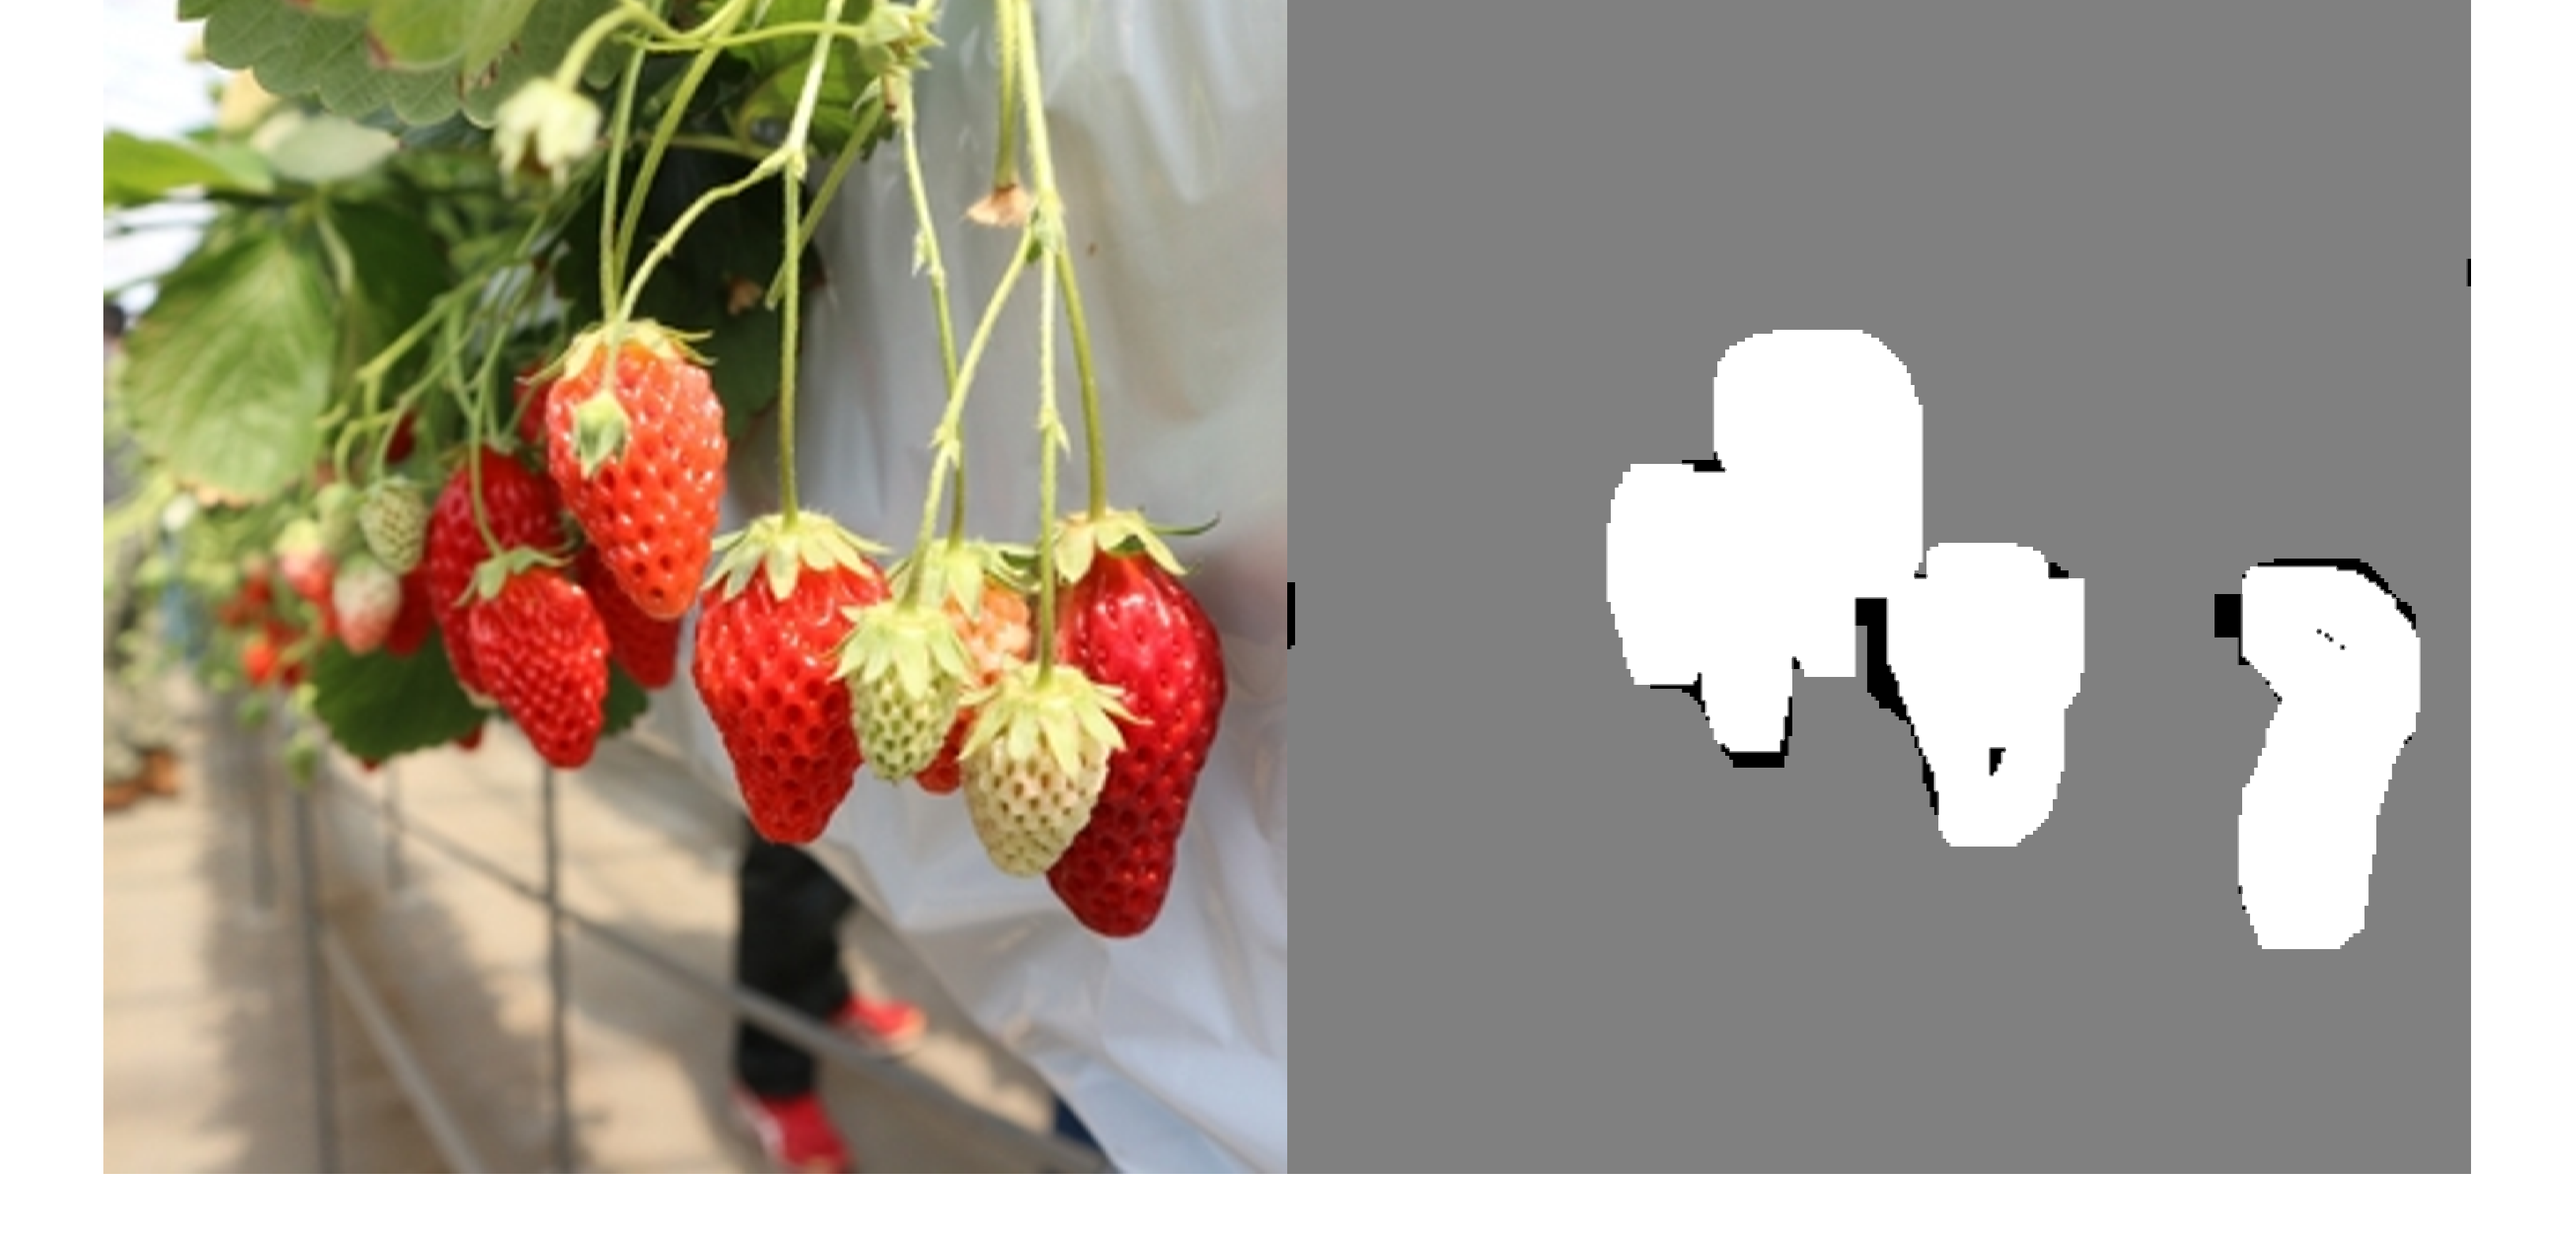

I = read(imds);
C = read(pxds);
I = imresize(I,5);
C = imresize(uint8(C{1}),5);
figure
imshowpair(I,C,'montage');

tbl = countEachLabel(trainingData)

tbl = 2×3 table
      Name       PixelCount    ImagePixelCount
    _________    __________    _______________

    {'itigo'}    2.2403e+06       2.97e+06    
    {'nouen'}    7.2128e+05       2.97e+06    


totalNumberOfPixels = sum(tbl.PixelCount);
freq = tbl.PixelCount / totalNumberOfPixels;
ClassWeights = 1./freq

ClassWeights =     1.3220
    4.1060


pxLayer = pixelClassificationLayer('Classes',tbl.Name,'ClassWeights',ClassWeights,'Name','pxLayer');
imageSize = [300 300 3];
numClasses = 2;
encoderDepth = 5

encoderDepth = 5

lgraph = segnetLayers(imageSize,numClasses,encoderDepth)

lgraph =   LayerGraph のプロパティ:

         Layers: [73×1 nnet.cnn.layer.Layer]
    Connections: [82×2 table]
     InputNames: {'inputImage'}
    OutputNames: {'pixelLabels'}


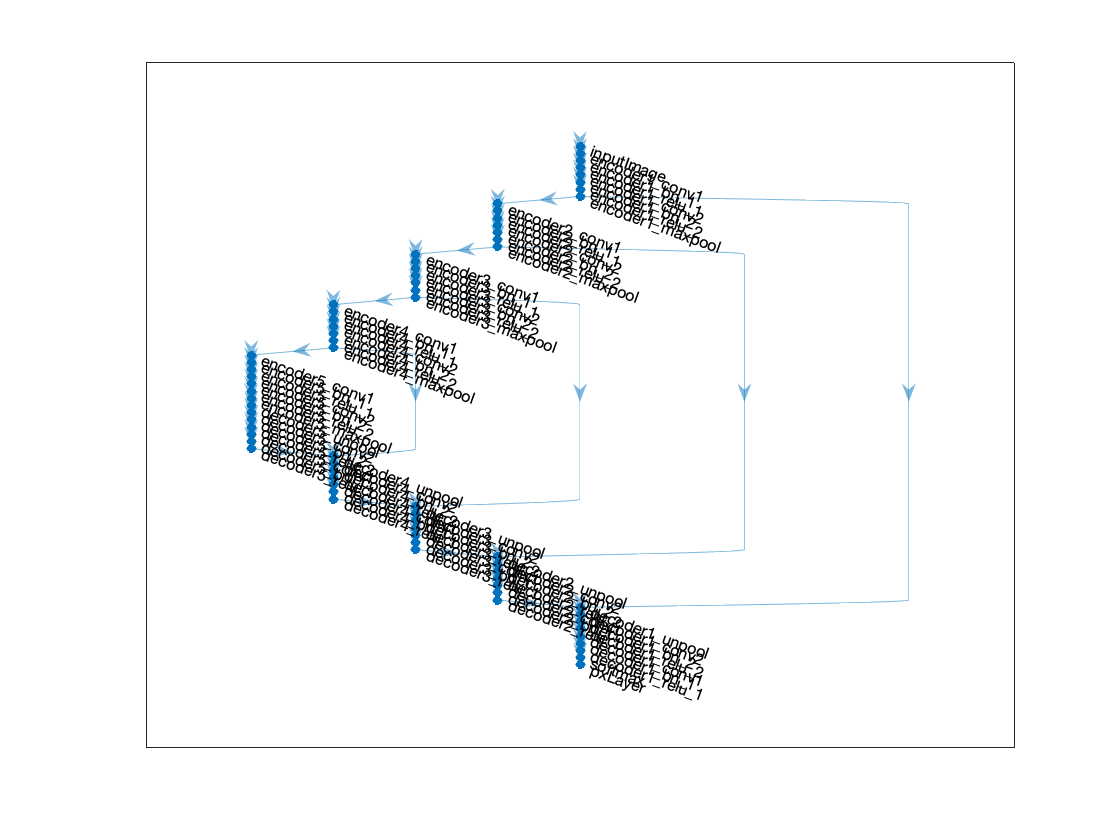

lgraph = removeLayers(lgraph,'pixelLabels');
lgraph = addLayers(lgraph,pxLayer);
lgraph = connectLayers(lgraph,'softmax','pxLayer');
figure
plot(lgraph)

opts = trainingOptions('adam', ...
    'InitialLearnRate',1e-3, ...
    'L2Regularization',0.0005,...
    'LearnRateDropPeriod',20,...
    'LearnRateDropFactor',0.1,...
    'ValidationData',pximdsVal,...
    'Shuffle',"every-epoch",...
    'ValidationFrequency',200,...
    'ValidationPatience',10,...
    'MaxEpochs',5,...
    'MiniBatchSize',1, ...
    'Plots',"training-progress" ,...
    'ResetInputNormalization',true  ,...
    'VerboseFrequency',200)

opts =   TrainingOptionsADAM のプロパティ:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 1.0000e-03
             LearnRateSchedule: 'none'
           LearnRateDropFactor: 0.1000
           LearnRateDropPeriod: 20
              L2Regularization: 5.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 5
                 MiniBatchSize: 1
                       Verbose: 1
              VerboseFrequency: 200
                ValidationData: [1×1 pixelLabelImageDatastore]
           ValidationFrequency: 200
            ValidationPatience: 10
                       Shuffle: 'every-epoch'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
                  

単一の CPU で学習中。
入力データの正規化を初期化しています。


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチの精度　　｜　　検証精度　　｜　　ミニバッチ損失　　｜　　検証損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　　　　１　｜　　　　１　｜　　　　　００：００：２７　｜　　　　　５６．４２％　｜　６１．８０％　｜　　　　０．７８７９　｜　０．７５５０　｜　　０．００１０　｜


｜　　　　　　５　｜　　１６５　｜　　　　　００：０５：１２　｜　　　　　７６．０２％　｜　６９．３３％　｜　　　　０．４４８２　｜　０．５４３６　｜　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


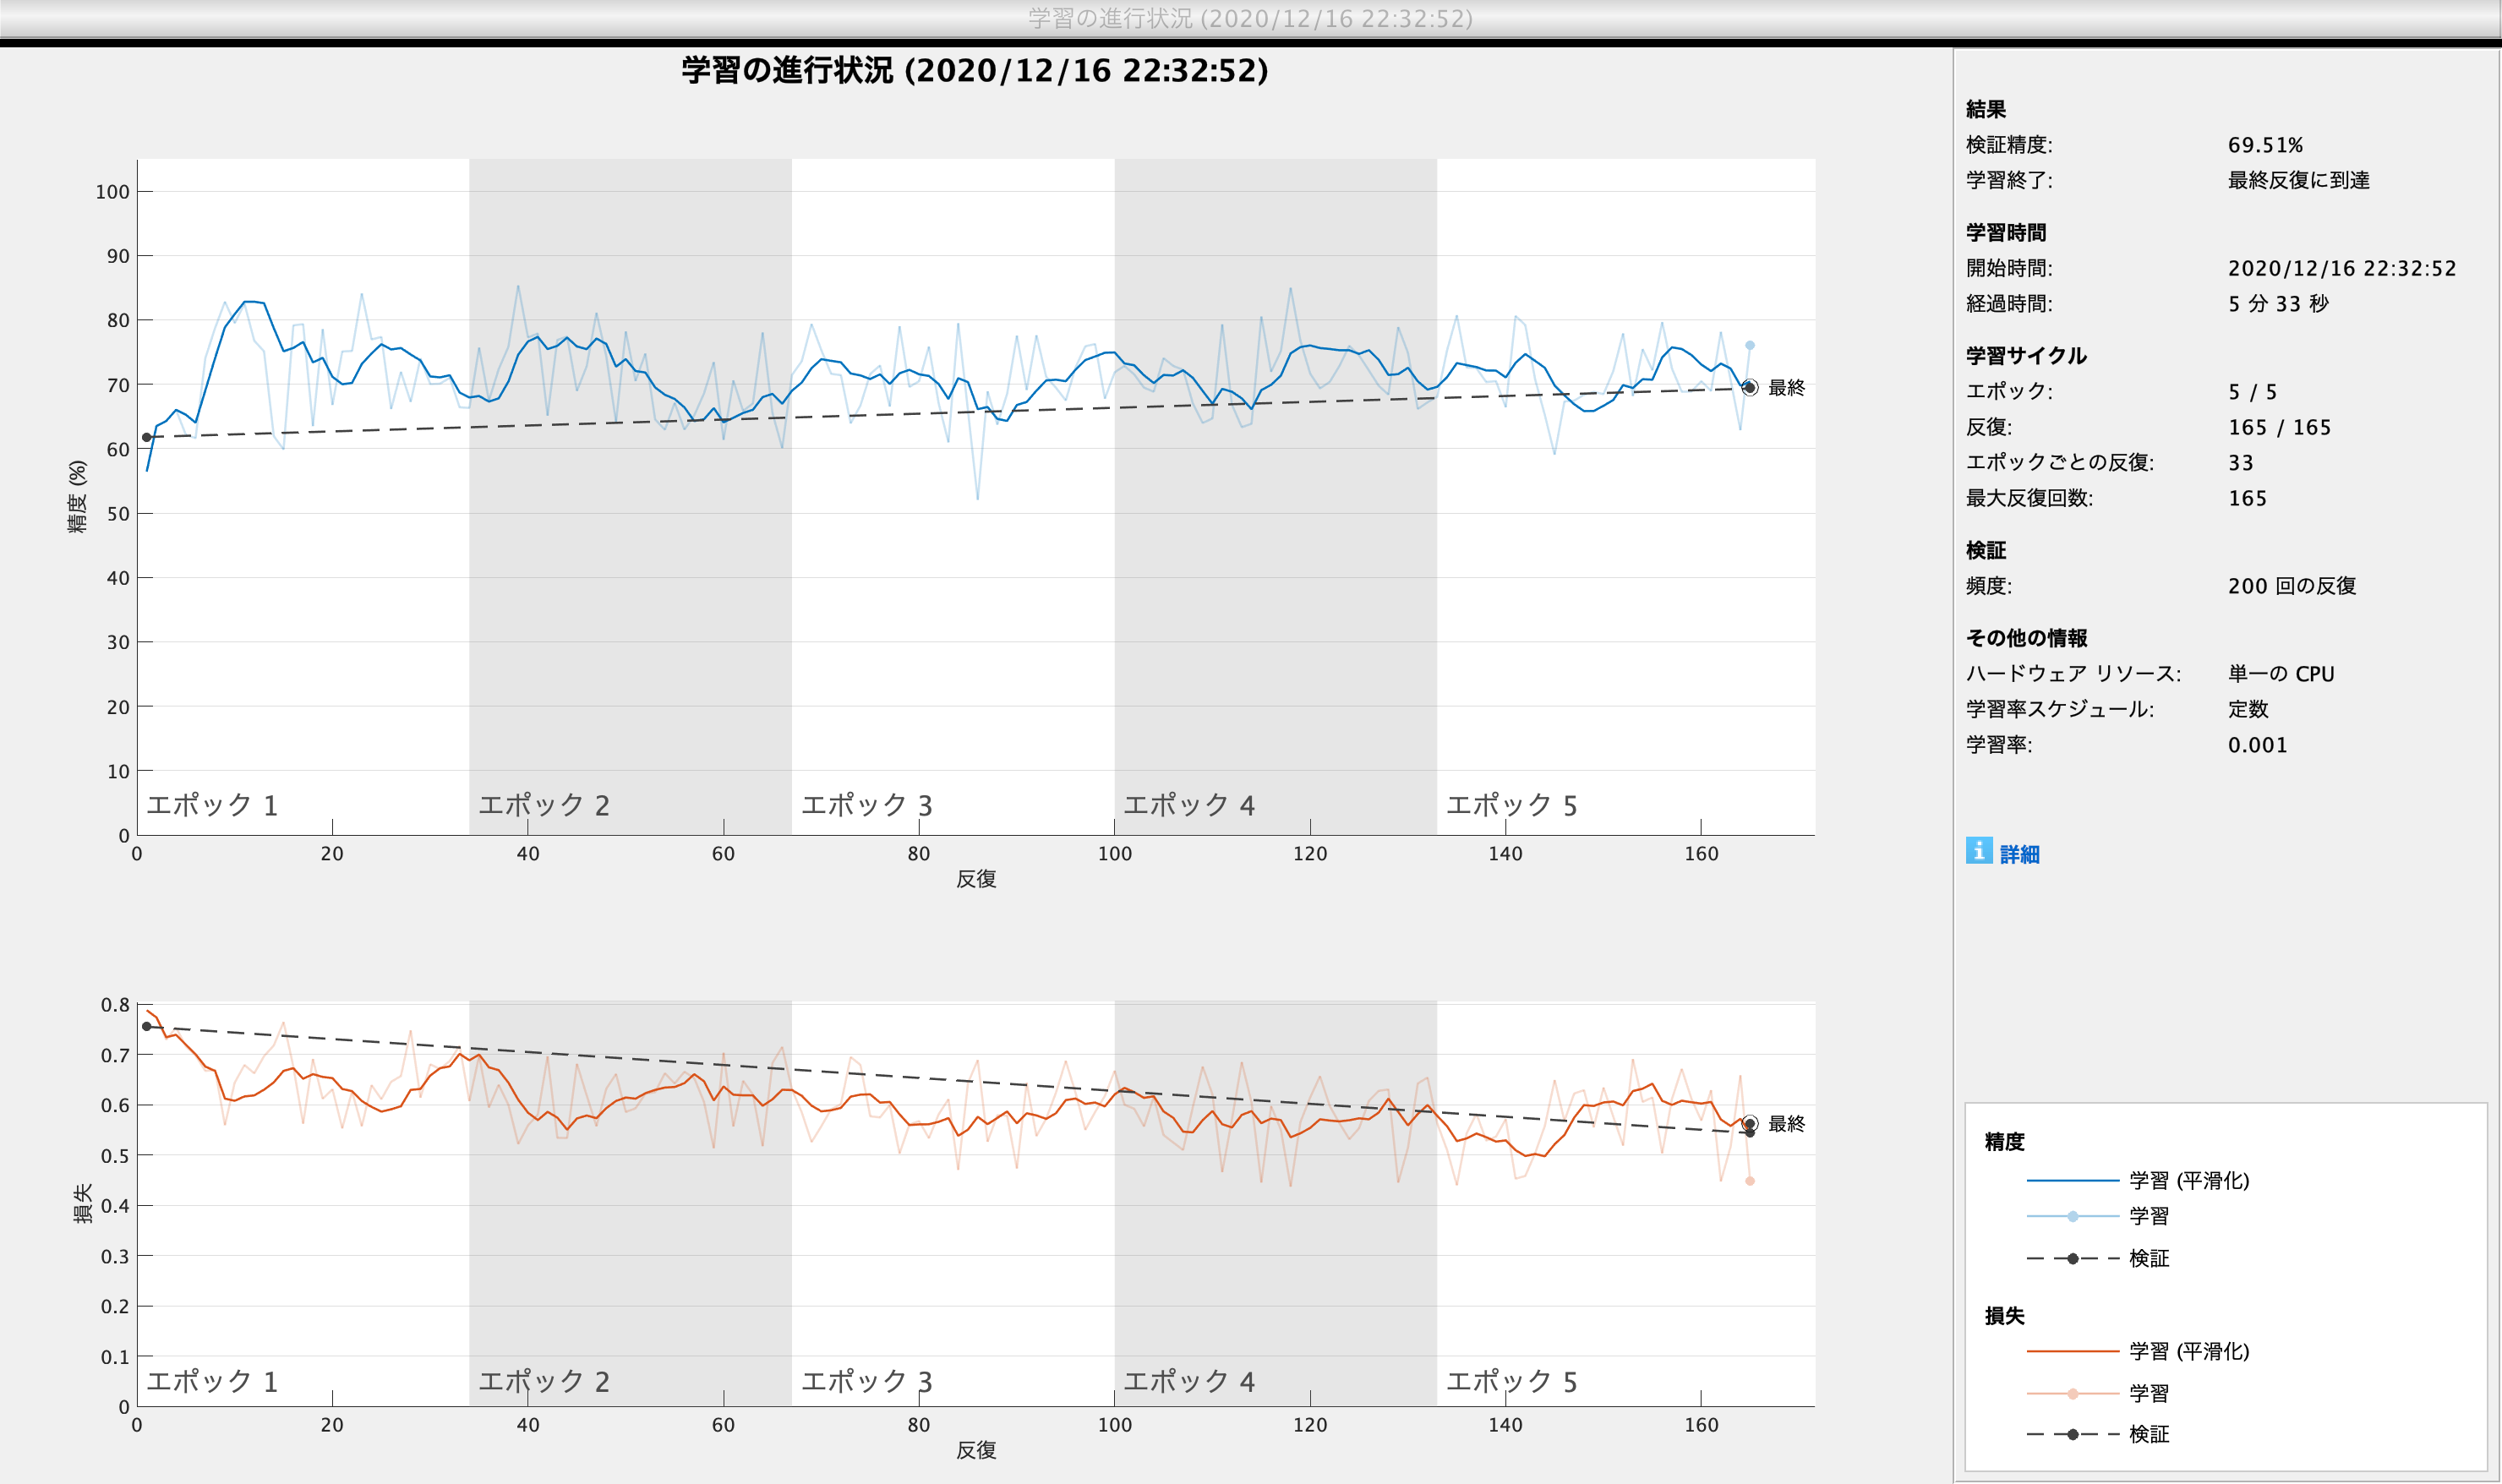

net = trainNetwork(trainingData,lgraph,opts);

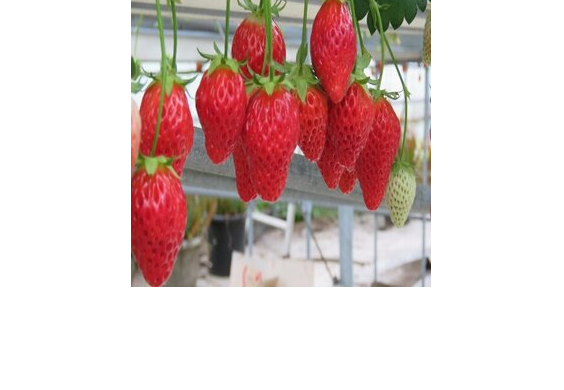

testImage = imread("data/itigo8.jpeg");
figure
figure,imshow(testImage)

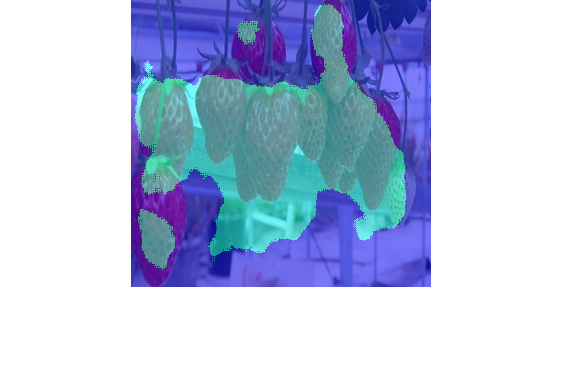

C = semanticseg(testImage,net);
B = labeloverlay(testImage,C);
figure,imshow(B)